## The Manny Ramirez problem, part 2

In the previous notebook I proposed this question inspired by the former Red Sox player Manny Ramirez:

*What is the minimum effort required to hit a home run in Fenway Park?*

To solve this problem, we’ll proceed in the following steps:

- We'll model the flight of a baseball, taking into account air resistance and gravity, and implement the model using ode45.

- For a given initial velocity, we’ll find the optimal "launch angle", that is, the angle the ball should leave home plate to maximize its height when it reaches the wall.

- Then we’ll find the minimal velocity that clears the wall, given that it has the optimal launch angle.

We did the first two parts in the previous notebook.  Now we're ready for the last part.

But first, we have to make some changes.  In the previous notebook we found the launch angle that maximizes range, that is, the distance the ball travels before it lands.  But for the Manny Ramirez problem, we want a different kind of "optimal": we want the angle that maximizes the height of the ball when it reaches the wall.

So, let's add the dimensions of Fenway Park to the `params` object:

clear all

params.wall_range = 94.5;  % meters
params.wall_height = 11;  % meters

The rest of the parameters are the same as in the previous notebook.

% initial x and y coordinates
params.x = 0; % m 
params.y = 1; % m

% acceleration due to gravity
params.g = 9.8; % m/s**2

% mass and diameter of a baseball from 
% https://en.wikipedia.org/wiki/Baseball_(ball)
params.mass = 145e-3; % kg
params.diameter = 73e-3; % m

% density of air at 20 C near sea level
params.rho = 1.2; % kg/m**3

% coefficient of drag for a baseball
params.C_d = 0.33;  % dimensionless

% launch angle and initial speed
params.launch_angle = 45; % degree
params.speed = 40; % m / s

params

params = struct with fields:
      wall_range: 94.5000
     wall_height: 11
               x: 0
               y: 1
               g: 9.8000
            mass: 0.1450
        diameter: 0.0730
             rho: 1.2000
             C_d: 0.3300
    launch_angle: 45
           speed: 40


If you look at the functions below, you'll see that I've changed `event_func` to stop when the ball reaches the wall, rather than when it hits the ground.

We can test it by running the ODE solver.

[T, M] = run_ode_solver(params);

And extracting the final coordinates.

X = M(:, 1);
Y = M(:, 2);

t_final = T(end)

t_final = 4.6734

x_range = X(end)

x_range = 94.5000

y_final = Y(end)

y_final = 6.9464

Here's the trajectory.

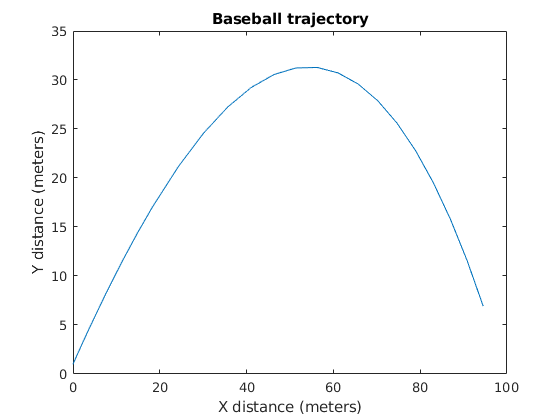

figure()
plot(X, Y)
xlabel('X distance (meters)')
ylabel('Y distance (meters)')
title('Baseball trajectory')

The final height is 6.9 meters, so this is not a home run.

### Optimal launch angle

I've replaced `range_func` with `height_func`, which returns the height of the ball when it reaches the wall.

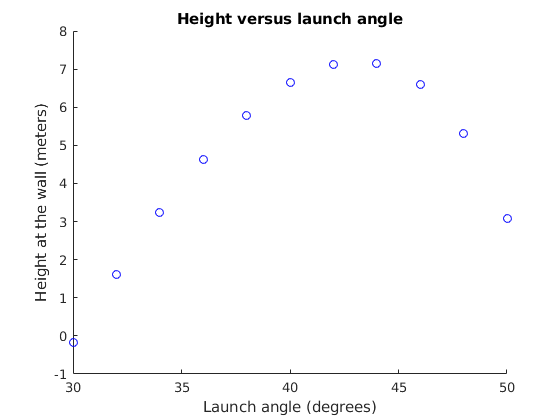

figure()
hold on
for launch_angle=linspace(30, 50, 11)
    height = height_func(launch_angle, params);
    plot(launch_angle, height, 'bo')
end
xlabel('Launch angle (degrees)')
ylabel('Height at the wall (meters)')
title('Height versus launch angle')

It looks like the peak is near 45 degrees.  Now we can use `fminsearch` to find the launch angle that maximizes height.

[x, fval] = fminsearch(@(x) -height_func(x, params), 45)

x = 43.0966

fval = -7.1977

With the initial speed 40 m/s, the launch angle that maximizes height is about 43 degrees, a little higher than the angle that maximizes range.

But even at the optimal angle, the final height is about 7 meters, not enough to get over an 11 meter wall.

### Minimal speed

To find the minimum speed that gets the ball over the wall I've defined an error function that takes speed as an input variable, uses `fminsearch` to find the optimal angle, runs the ODE solver with that angle, and returns the difference between the final height and the goal, 11 meters.

We can test it with a range of values.

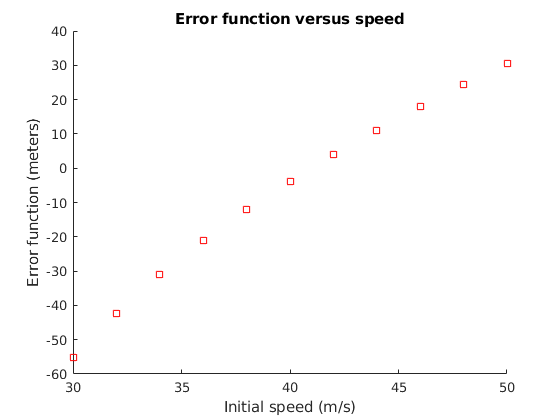

figure()
hold on
for speed=linspace(30, 50, 11)
    error = error_func(speed, params);
    plot(speed, error, 'rs')
end
xlabel('Initial speed (m/s)')
ylabel('Error function (meters)')
title('Error function versus speed')

It looks like it passes through 0 when speed is near 40 m/s.

Now we can use `fzero` to find the initial speed that yields final height 11 meters.

minimum_speed = fzero(@(x) error_func(x, params), 40)

minimum_speed = 40.9718

The minimum speed the ball can leave home plate is just under 41 m/s.  

Many baseball players can throw a ball that fast, which means they could stand on home plate and [throw a ball over the Green Monster](https://www.youtube.com/watch?v=0AnpKBxr9AM).

### Functions

function [T, M] = run_ode_solver(params)
    % Simulate the flight of a baseball.
    
    % Compute the initial condition vector
    theta = deg2rad(params.launch_angle);
    [vx, vy] = pol2cart(theta, params.speed);
    init = [params.x, params.y, vx, vy];
    
    % compute baseball area (for drag force)
    radius = params.diameter/2;
    area = pi * radius^2;
    
    % Test the slope function
    slope_func(0, init);
    
    options = odeset('Events', @event_func);
    
    % Run ode45
    tspan = [0, 10];  % seconds
    [T, M] = ode45(@slope_func, tspan, init, options);
    
    function res = slope_func(t, X)
        % Compute slope for the baseball model.
        [x, y, vx, vy] = matsplit(X);
        
        V = [vx, vy];
        a_drag = drag_force(V) / params.mass;
        a_grav = [0, -params.g];
    
        A = a_grav + a_drag;
        
        res = [vx; vy; A(1); A(2)];
    end
    
    function [value, isterminal, direction] = event_func(t, X)
        % Stop when the ball hits reaches the wall.
        [x, y, vx, vy] = matsplit(X);
        value = x - params.wall_range;
        isterminal = 1;
        direction = 1;
    end
    
    function res = drag_force(V)
        % Compute the drag force on a baseball.
        rho = params.rho;
        C_d = params.C_d;
        mag = -rho * norm(V)^2 * C_d * area / 2;
        direction = hat(V);
        res = direction * mag;
    end
end

function res = hat(V)
    % Compute a unit vector in the direction of V.
    res = V / norm(V);
end
    
function res = height_func(launch_angle, params)
    % Height of the ball when it reaches wall.
    params.launch_angle = launch_angle;
    [T, M] = run_ode_solver(params);
    Y = M(:, 2);
    res = Y(end);
end

function res = error_func(speed, params)
    % Find the launch angle that maximizes height
    % at the wall and return the difference between
    % the measured height and the goal.
    params.speed = speed;
    [x, fval] = fminsearch(@(x) -height_func(x, params), 40);
    params.launch_angle = x;
    [T, M] = run_ode_solver(params);
    Y = M(:, 2);
    res = Y(end) - params.wall_height;
end

function varargout = matsplit(A,dim)
%MATSPLIT Split matrix elements into separate variables.
%   VARARGOUT = MATSPLIT(A) returns each element of the array A in a
%   separate variable defined by VARARGOUT.
%
%   VARARGOUT = MATSPLIT(A,DIM) only splits the matrix in one dimension. If
%   DIM=1, each column vector is assigned to an output variable. If
%   DIM=2, each row vector is assigned to an output variable.
%
%   MRE 11/12/14 (last updated 11/13/14)
%   https://www.mathworks.com/matlabcentral/fileexchange/48439-matsplit
    if nargin==1
        varargout = num2cell(A);
    else
        varargout = num2cell(A,dim);
    end
end